# Ex11. Introduction to Signals and systems

### s1320112/ Motohisa YAMANO

## 1. Compare IIR filter Transfer Function

 This assignment focuses on generating figures that represent the frequency response of an IIR filter. We evaluate the transfer function H(z) in both its original form and its partial fraction expansion. Numerical computation was performed with a resolution of N = 1024 points. To facilitate a comparative analysis, the resulting magnitude and phase characteristics are organized into a 4x2 subplot grid .

#### 1.1. MATLAB Code

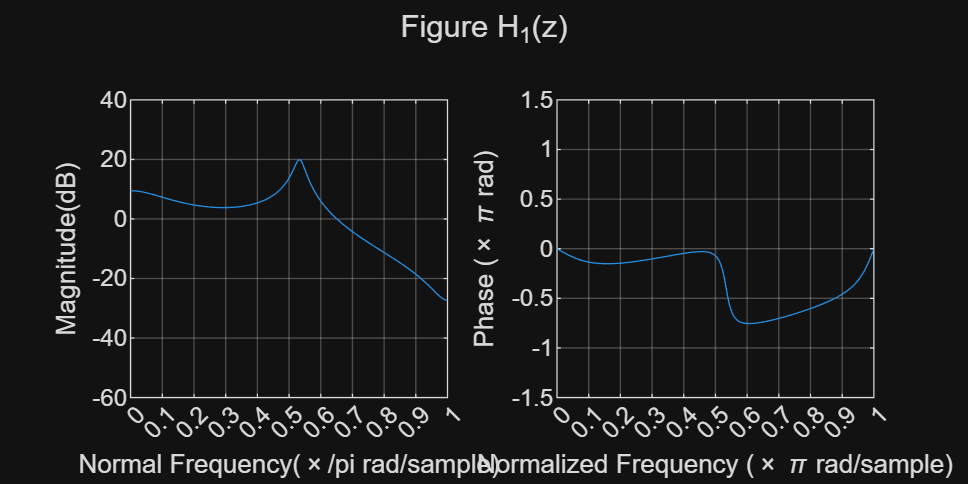

N = 1024;

b0 = [1];
b1 = [1 0.875];
b2 = [1];

a1 = [1 0.2 0.9];
a2 = [1 -0.7];

b = b0*conv(b1, b2);
a = conv(a1, a2);
[h1, w1] = freqz(b, a, 'half', N);

b21 = [19/68 63/68];
a21 = [1 0.2 0.9];
[h21, w21] = freqz(b21, a21, 'half', N);

b22 = [49/68];
a22 = [1 -0.7];
[h22, w22] = freqz(b22, a22, 'half', N);

h2 = h21 + h22;

figure('Position', [100 100 1600 800]);
subplot(1, 2, 1);
plot(w1/pi, 20*log10(abs(h1)));
grid on;
ax = gca;
ax.YLim = [-60 40];
ax.XTick = 0:.1:1;
xlabel('Normal Frequency(\times/pi rad/sample)');
ylabel('Magnitude(dB)');

subplot(1, 2, 2);
plot(w1/pi, phase(h1)/pi);
grid on;
ax = gca;
ax.YLim = [-1.5 1.5];
ax.XTick = 0:0.1:1;
xlabel('Normalized Frequency (\times \pi rad/sample)');
ylabel('Phase (\times \pi rad)');
sgtitle('Figure H_1(z)');

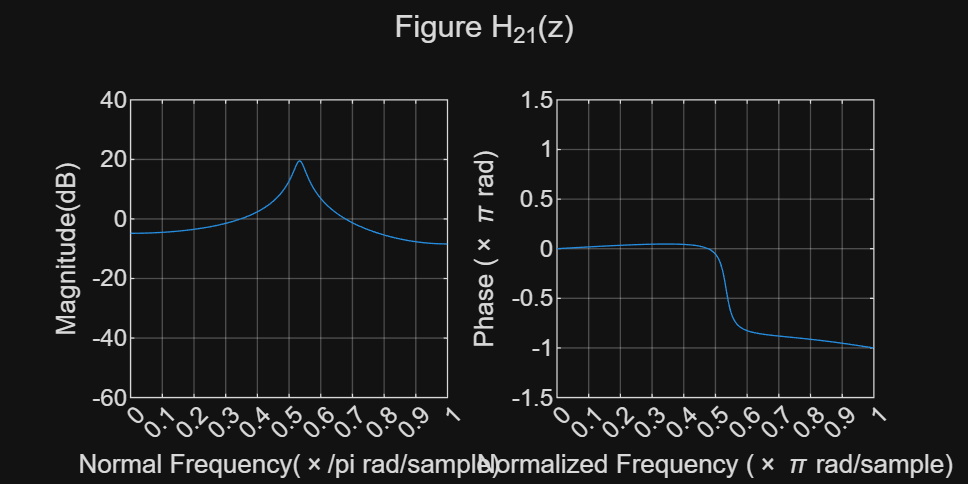



figure('Position', [100 100 1600 800]);
subplot(1, 2, 1);
plot(w21/pi, 20*log10(abs(h21)));
grid on;
ax = gca;
ax.YLim = [-60 40];
ax.XTick = 0:.1:1;
xlabel('Normal Frequency(\times/pi rad/sample)');
ylabel('Magnitude(dB)');

subplot(1, 2, 2);
plot(w21/pi, phase(h21)/pi);
grid on;
ax = gca;
ax.YLim = [-1.5 1.5];
ax.XTick = 0:0.1:1;
xlabel('Normalized Frequency (\times \pi rad/sample)');
ylabel('Phase (\times \pi rad)');
sgtitle('Figure H_{21}(z)');

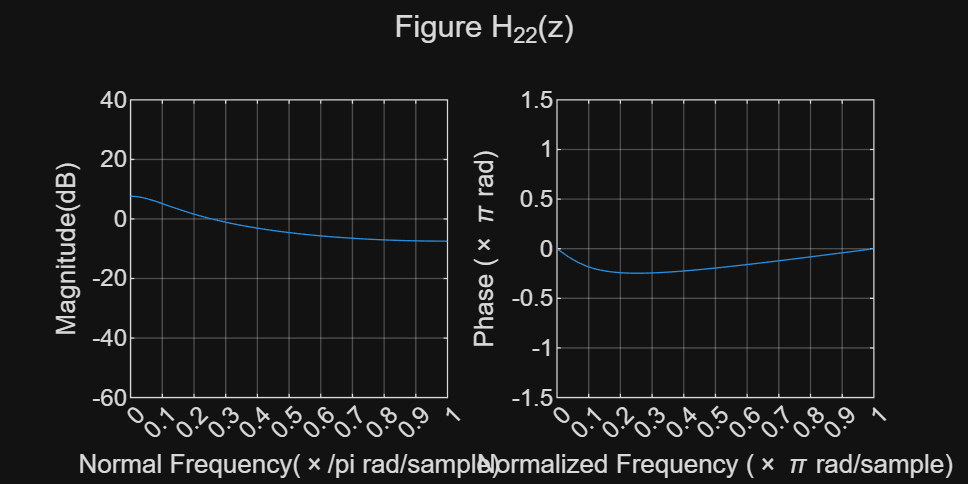



figure('Position', [100 100 1600 800]);
subplot(1, 2, 1);
plot(w22/pi, 20*log10(abs(h22)));
grid on;
ax = gca;
ax.YLim = [-60 40];
ax.XTick = 0:.1:1;
xlabel('Normal Frequency(\times/pi rad/sample)');
ylabel('Magnitude(dB)');

subplot(1, 2, 2);
plot(w22/pi, phase(h22)/pi);
grid on;
ax = gca;
ax.YLim = [-1.5 1.5];
ax.XTick = 0:0.1:1;
xlabel('Normalized Frequency (\times \pi rad/sample)');
ylabel('Phase (\times \pi rad)');
sgtitle('Figure H_{22}(z)');

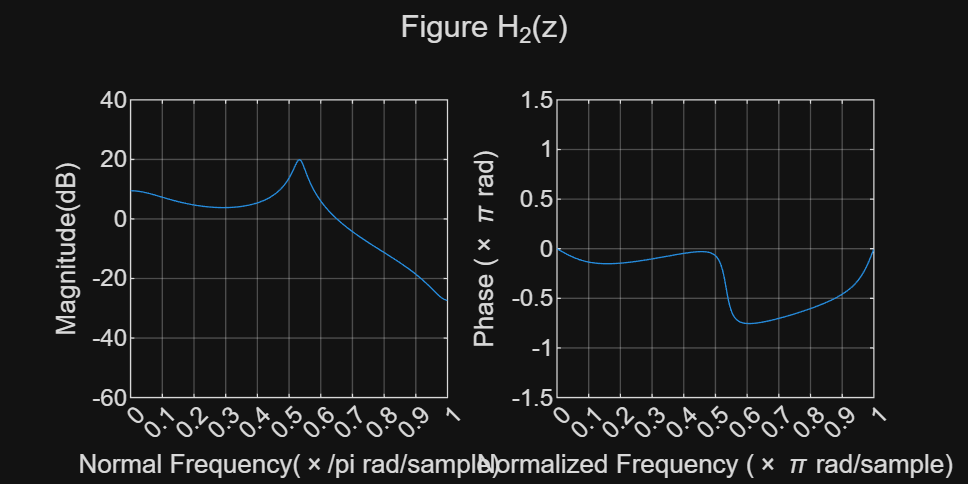



figure('Position', [100 100 1600 800]);
subplot(1, 2, 1);
plot(w22/pi, 20*log10(abs(h2)));
grid on;
ax = gca;
ax.YLim = [-60 40];
ax.XTick = 0:.1:1;
xlabel('Normal Frequency(\times/pi rad/sample)');
ylabel('Magnitude(dB)');

subplot(1, 2, 2);
plot(w22/pi, phase(h2)/pi);
grid on;
ax = gca;
ax.YLim = [-1.5 1.5];
ax.XTick = 0:0.1:1;
xlabel('Normalized Frequency (\times \pi rad/sample)');
ylabel('Phase (\times \pi rad)');
sgtitle('Figure H_2(z)');

#### 1.2. Discussion 

 The figures for H_1 and H_2 show that their frequency responses are the same. The result can be explained mathematically. H_2 is obtained by applying partial fraction expansion to H_1, where H_1 is decomposed into H_21 and H_22. Since, H_1 = H_21 + H_22 = H_2 this relationship is an algebraic identity. 

 Therefore, the transfer functions of H_1 and H_2 are identical. Consequently, their frequency responses, which are obtained by evaluating the transfer functions on the unit circle z=exp(j*ω), must also be identical.

## 2. Math Problem 

Below is the snapshot of my answer in fill-blank math problem. 